# Homework #7

Victoria Subritzky Katz

09/27/2023

## Q1

1. Plot X vs Y. Do they look related?

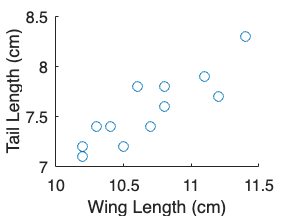

X = [10.4,10.8,11.1,10.2,10.3,10.2,10.7,10.5,10.8,11.2,10.6,11.4];
Y = [7.4,7.6,7.9,7.2,7.4,7.1,7.4,7.2,7.8,7.7,7.8,8.3];

figure
scatter(X,Y)
xlabel('Wing Length (cm)')
ylabel('Tail Length (cm)')

The wing length (X) and tail length (Y) look like they could have a positive correlation.

## Q2

Calculate rX,Yand rY,X first using the equations above and then using either the Python numpy funciton [corrcoef](https://numpy.org/doc/stable/reference/generated/numpy.corrcoef.html) or Matlab's built-in [corrcoef](https://www.mathworks.com/help/matlab/ref/corrcoef.html). Did you get the same answers?

%calculate the means of the distributions
X_mean = mean(X);
Y_mean = mean(Y);

%calculate the pearson's corellation coefficient using the given equations
r_xy_calc = pearsons_CC(X,X_mean,Y,Y_mean);
r_yx_calc = pearsons_CC(Y,Y_mean,X,X_mean);

fprintf("The Pearson's correlation coefficient calculated mathematically is r_X,Y=%.4f and r_Y,X=%.4f ",r_xy_calc,r_yx_calc)

The Pearson's correlation coefficient calculated mathematically is r_X,Y=0.8704 and r_Y,X=0.8704 


%calculate the pearson's corellation coefficient using the built in function
r_xy_built = corrcoef(X,Y);
r_xy_built = r_xy_built(1,2); 
r_yx_built = corrcoef(Y,X);
r_yx_built = r_yx_built(1,2);

fprintf("The Pearson's correlation coefficient calculated using the built in function is r_X,Y=%.4f and r_Y,X=%.4f ",r_xy_built,r_yx_built)

The Pearson's correlation coefficient calculated using the built in function is r_X,Y=0.8704 and r_Y,X=0.8704 

I arrived at the same correlation coefficient value when using the given equation vs the built in function and when calculating the XY vs YX correlation. 

## Q3

What is the standard error of rX,Y? The 95% confidence intervals computed from the standard error?

%set confidence interval 
confidence_int = .95; 

%calculate the standard error of the r_X,Y pearson's corellation coefficient
standard_error = sqrt((1-r_xy_calc^2)/(length(X)-2)); 

%z-transform
z = .5*(log((1+r_xy_calc)/(1-r_xy_calc)));

%compute standard deviation
s_z = sqrt(1/(length(X)-3));

%compute confidence intervals in z-space
z_pos = z+norminv(confidence_int)*s_z;
z_neg = z-norminv(confidence_int)*s_z;

%translate z values to r
r_conf(1) = (exp(2*z_pos)-1)/(exp(2*z_pos)+1);
r_conf(2) = (exp(2*z_neg)-1)/(exp(2*z_neg)+1);

fprintf('The standard error of r_X,Y is %.4f',standard_error)

The standard error of r_X,Y is 0.1557

fprintf('The %d%% confidence interval of r_X,Y is %.4f to %.4f',confidence_int*100,r_conf(1),r_conf(2))

The 95% confidence interval of r_X,Y is 0.9547 to 0.6563

## Q4

Should the value of rX,Y be considered significant at the *p*<0.05 level, given a two-tailed test (i.e., we reject if the test statistic is too large on either tail of the null distribution) for H_0: rX,Y=0?

%calculate t value for H0: r = 0
t_0 = r_xy_calc/standard_error; 

Using a t-Table for a two-sided alpha with 10 degrees of freedom (n-2) and p=0.05, the critical value is 2.23. Thus, our result for rX,Y is significant at p=.05 as our calculated t value of 5.5893 is greater than 2.23, so we can reject the null hypothesis. 

## Q5

Yale does the exact same study and finds that his correlation value is 0.75. Is this the same as yours? That is, evaluate 𝐻0: r=0.75.

yale_r = .75;
yale_z = .5*(log((1+yale_r)/(1-yale_r)));
lambda = z-yale_z/sqrt(1/(12-3));

I cannot show statistically that Yale's result is different from mine, as the calculated lambda is -1.5843 and that is neither larger than 2.23 or smaller than -2.23.

## Q6

Finally, calculate the statistical power and sample size needed to reject H0: r=0 when r ≥0.5.

effect_size = .5;
p = 0.5; 




function corelation_coef = pearsons_CC(x,x_mean,y,y_mean)
    corelation_coef = sum((x-x_mean) .* (y-y_mean))/(sqrt(sum((x-x_mean).^2))*sqrt(sum((y-y_mean).^2)));
    
end
